%help LTspice2Matlab
raw_data = LTspice2Matlab('transfer function.RAW');
f=raw_data.freq_vect;

variable_to_plot = [59]

variable_to_plot = 59

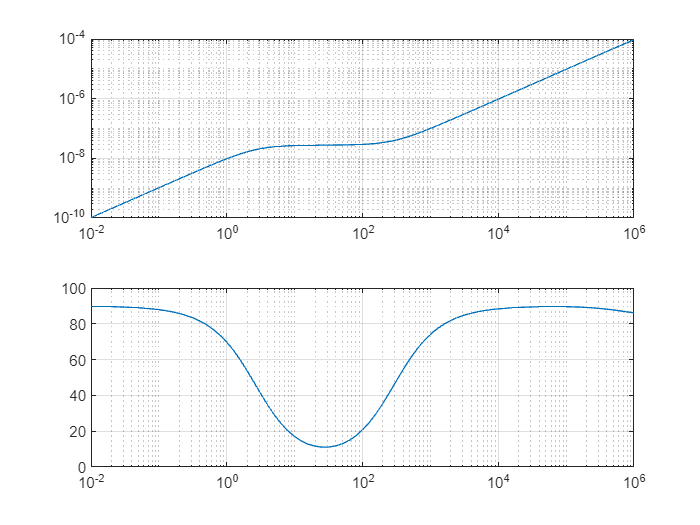

A1=squeeze(raw_data.variable_mat(variable_to_plot,:)).';

% Magnitude plot
magA1 = abs(A1);
subplot(2, 1, 1);
loglog(f,magA1);
grid on;

% Phase plot
phA1 = angle(A1);
subplot(2, 1, 2);
semilogx(f,rad2deg(phA1));
grid on;


Mag = magA1;
PhDeg = phA1;
Response = Mag.*exp(1j*PhDeg);
Ts = 0;
sysfr = idfrd(Response, f, Ts, 'FrequencyUnit','Hz')

sysfr =

IDFRD model.
Contains Frequency Response Data for 1 output(s) and 1 input(s).
Response data is available at 81 frequency points, ranging from 0.01 Hz to 1e+06 Hz.
 
Status:                                                         
Created by direct construction or transformation. Not estimated.
 
Model Properties


OLTFog = tfest(sysfr,6)

OLTFog =
         -1.035e06 s^5 - 1.454e13 s^4 - 2.607e19 s^3 - 1.259e25 s^2 - 2.266e28 s
  -------------------------------------------------------------------------------------
  s^6 - 6.45e07 s^5 - 7.875e16 s^4 - 9.641e23 s^3 - 1.704e30 s^2 - 8.18e35 s - 1.379e37
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 6   Number of zeros: 5
   Number of free coefficients: 12
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                  
Estimated using TFEST on frequency response data "sysfr".
Fit to estimation data: 99.85%                           
FPE: 8.585e-16, MSE: 6.369e-16                           
 


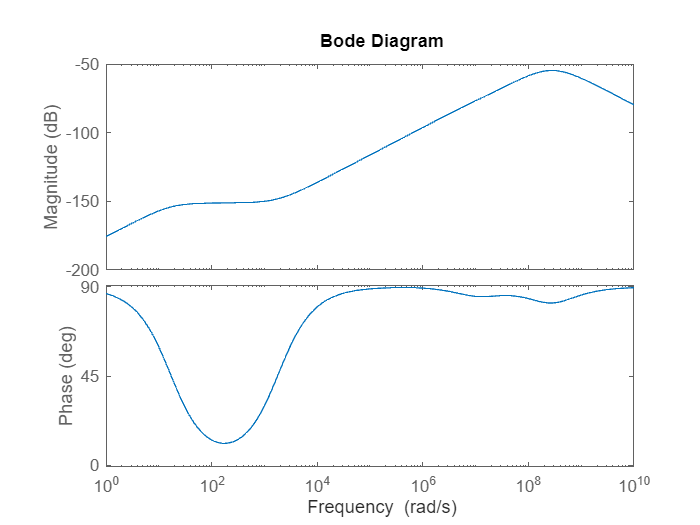

figure
bode(OLTFog)

OLTFnum = OLTFog.Numerator;
OLTFden = OLTFog.Denominator;
csvwrite('OLTFnum.csv', OLTFnum);
csvwrite('OLTFden.csv', OLTFden);